This live script solves the 2D first-order acoustic equations using four perfectly matched layers. Pressure is split into two directionally damped fields internally, but the solver returns their sum.

clear; close all; clc;

%% Computational and output grids
domain = [0,1];
grid_cmp = GridSpace2D( ...
    Grid1DUnifPrimal(domain,161), ...
    Grid1DUnifPrimal(domain,161));
grid_out = GridSpace2D( ...
    Grid1DUnifPrimal(domain,81), ...
    Grid1DUnifPrimal(domain,81));

%% Medium and acoustic source
medium = AcousticMedium2D.constant(KappaValue=1,BetaValue=1);
source = AcousticSource2D( ...
    @(x,y) exp(-((x-0.40)/0.045).^2-((y-0.55)/0.045).^2), ...
    @(t) exp(-((t-0.08)/0.018).^2));

%% Stable time grids
[~,~,~,~,cMax] = sampleMedium2D(grid_cmp,medium);
spatialOrder = 4;
cflLimit = 6/7;
dt = 0.80*cflLimit/(cMax*sqrt(sum(1./grid_cmp.h.^2)));
finalTime = 1.2;
times_cmp = 0:dt:finalTime;
times_out = linspace(0,times_cmp(end),81);

%% Initial data
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

%% Four-sided PML
pml = PML2D( ...
    WidthLeft=0.15,WidthRight=0.15, ...
    WidthBottom=0.15,WidthTop=0.15, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

solver = AcousticSolver2D_PML( ...
    grid_cmp,times_cmp,grid_out,times_out,medium,pml, ...
    SpatialOrder=spatialOrder);

%% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);

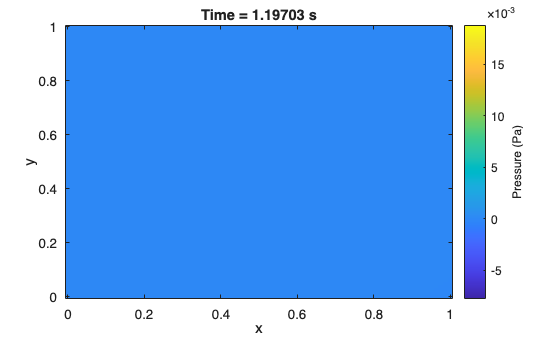

%% Animate pressure
ax = axes(figure(Name="Pressure with PML"));
P.animate(FramePause=0.03,Parent=ax);

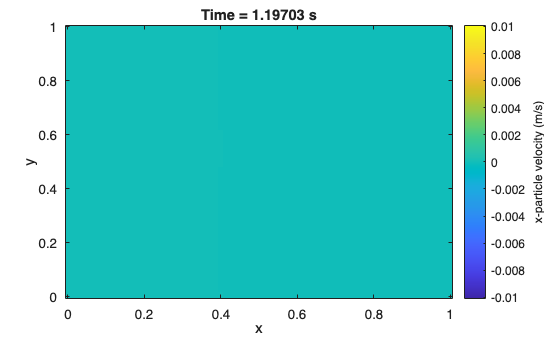

%% Animate velocity components
ax = axes(figure(Name="x-velocity with PML"));
Vx.animate(FramePause=0.03,Parent=ax);

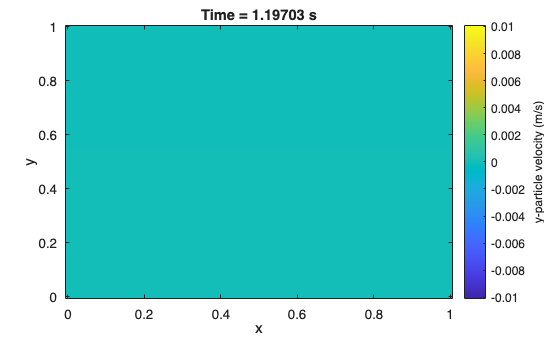


ax = axes(figure(Name="y-velocity with PML"));
Vy.animate(FramePause=0.03,Parent=ax);

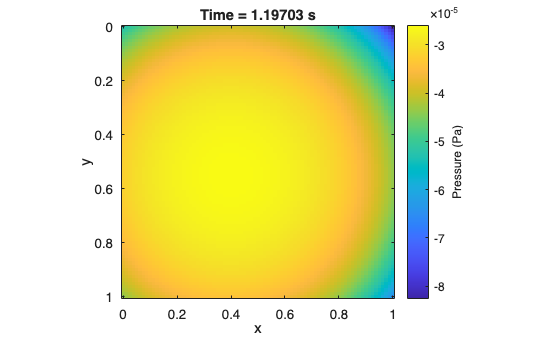

%% Final pressure snapshot
finalPressure = P.snapshot(P.Nt);
ax = axes(figure(Name="Final pressure with PML"));
finalPressure.plot(Parent=ax);
axis(ax,'image');
title(ax,P.formattedTime(P.Nt));